img = imread("Laberint.png");
% imshow(img)
% imgB = img(:, :, 3) == 232 & img(:, :, 2) == 162;
% imgR = img(:, :, 1) == 237 & img(:, :, 2) == 28 & img(:, :, 3) == 36;
% imgG = img(:, :, 1) == 34 & img(:, :, 2) == 177 & img(:, :, 3) == 76;

red_point = img(:, :, 1) > 100 & img(:, :, 2) < 100 & img(:, :, 3) < 100;
green_point = img(:, :, 2) > 100 & img(:, :, 1) < 100 & img(:, :, 3) < 100;
blue_point = img(:, :, 3) > 100 & img(:, :, 2) < 200 & img(:, :, 1) < 100;
[Rmx, Rmy] = get_middle(red_point);
[Gmx, Gmy] = get_middle(green_point);
[Bmx, Bmy] = get_middle(blue_point);


[dist_blue_dot, img_blue_dot] = BFS(img, Bmx, Bmy, Rmx, Rmy, blue_point, red_point);
dist_blue_dot

dist_blue_dot = 1332

[dist_green_dot, img_green_dot] = BFS(img, Gmx, Gmy, Rmx, Rmy, green_point, red_point);
dist_green_dot

dist_green_dot = 1013

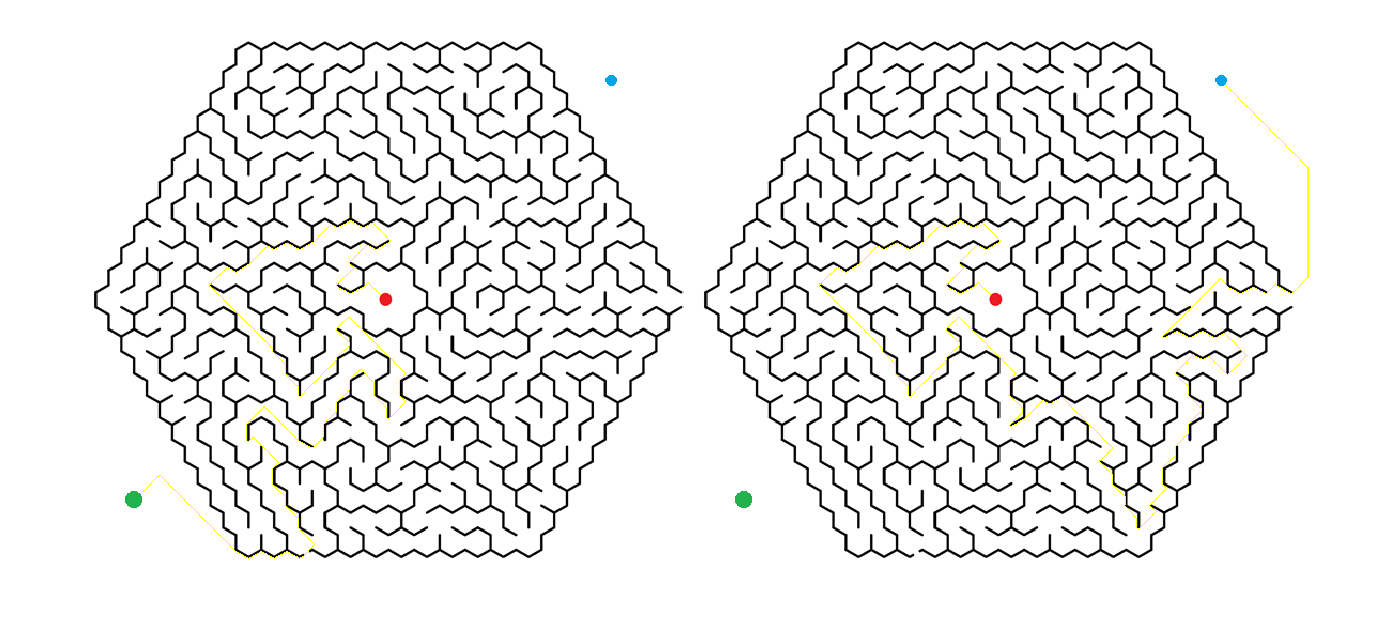

montage({img_green_dot, img_blue_dot})

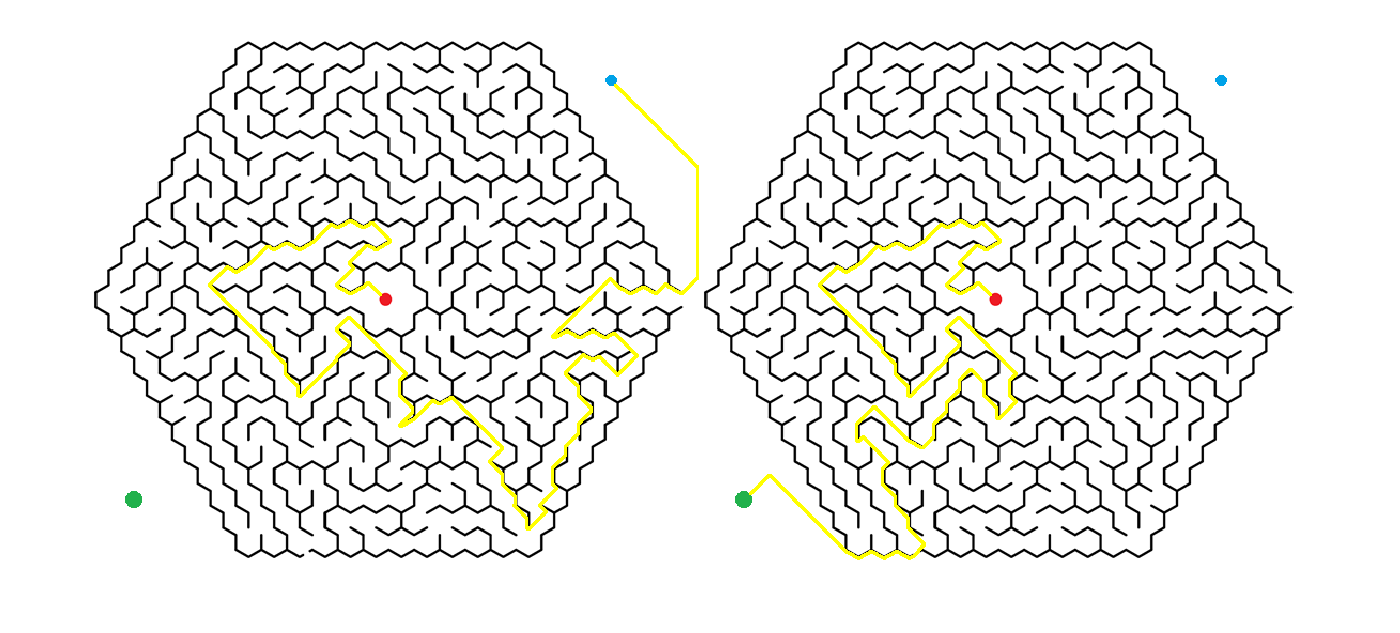

img_blue_red = img_blue_dot(:, :, 1) == 255 & img_blue_dot(:, :, 2) == 255 & img_blue_dot(:, :, 3) == 0;
SE = [1, 1, 1; 1, 1, 1; 1, 1 ,1];
img_blue_red = imdilate(img_blue_red, SE);
img_blue_red = imoverlay(img, img_blue_red);

img_green_red = img_green_dot(:, :, 1) == 255 & img_green_dot(:, :, 2) == 255 & img_green_dot(:, :, 3) == 0;
img_green_red = imdilate(img_green_red, SE);
img_green_red = imoverlay(img, img_green_red);

montage({img_blue_red, img_green_red})

function [dist, img] = BFS(img, sourceX, sourceY, destinationX, destinationY, ini, fin)
% Obtenemos los bordes del laberinto
bordes = rgb2gray(img);
bordes = bordes > 60;

% Matrices para conocer la posición previa
previousX(1:505, 1:570) = -1;
previousY(1:505, 1:570) = -1;
% Matriz que para conocer las distancias
distance(1:505, 1:570) = -1;
% Array que hace la función de una cola
queue(1).x = sourceX;
queue(1).y = sourceY;
distance(sourceX, sourceY) = 0;

% Posiciones adyacentes (vecinos)
moveX = [-1, 0, 1, -1, 1, -1, 0, 1];
moveY = [1, 1, 1, 0, 0, -1, -1, -1];
move.x = moveX;
move.y = moveY;

while (isempty(queue) == 0)
    x = queue(1).x;
    y = queue(1).y;
    queue = queue(2:end);
    
    if (x == destinationX && y == destinationY)
        dist = distance(x, y);
        break;
    end
    
    m = size(move.x);
    for i = 1:m(2)
        x1 = x + move.x(i);
        y1 = y + move.y(i);
        if (x1 <= 505 && 0 < x1 && y1 <= 570 && 0 < y1 && bordes(x1, y1) == 1)
            if (distance(x1, y1) == -1)
                distance(x1, y1) = distance(x, y) + 1;
                queue(end+1).x = x1;
                queue(end).y = y1;
                previousX(x1, y1) = x;
                previousY(x1, y1) = y;
            end
        end
    end
end

% Pintamos los píxeles que nos llevan por camino más corto de color amarillo
prevX = x; prevY = y;
while (prevX ~= -1)
    % Esta condicion la ponemos para que no pinte los puntos y no tenga
    % en cuente como distancia los píxeles dentro de los puntos
    if (ini(prevX, prevY) == 0 && fin(prevX, prevY) == 0)
        img(prevX, prevY, 1) = 255;
        img(prevX, prevY, 2) = 255;
        img(prevX, prevY, 3) = 0;
    else
        dist = dist - 1;
    end
    auxX = previousX(prevX, prevY);
    prevY = previousY(prevX, prevY);
    prevX = auxX;
end
end

function [mx, my] = get_middle(point)
m = size(point);
mxH = -1; myH = -1; mxL = -1; myL = -1;
for i = 1:m(1)
    for j = 1:m(2)
        if (point(i, j) == 1)
            if (mxH == -1)
                mxH = i;
                mxL = i;
                myL = j;
                myH = j;
            else
                if (i < mxL)
                    mxL = i;
                elseif (i > mxH)
                    mxH = i;
                end
                if (j < myL)
                    myL = j;
                elseif (j > myH)
                    myH = j;
                end
            end
        end
    end
end

mx = int16((mxH + mxL) / 2);
my = int16((myH + myL) / 2);
end
    